# Testing Ground for the Backtest Components: Test File & Data Structures

# Section 1: Preparation of Backtest Simulation 

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 14/09/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

**This file begins with setting up the backtest framework. The framework needs to accomodate several aspect to increase the functionality and usability:**

- **Standard backtetst**

- **Including constraints on assets e.g. 5% upper bound cash limit**

- **Winsorising the returns to control for outliers**

- **Regularisation of the covariance matrix **

 Here each point above is first tested in 'helper_fns_test_1"  before it is then implemented and tested in turn within this file.  Each can later be combined if desired. 

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath_ = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

% Load returns Data
fileName = 'DATA-PROCESSED-ASSETCL-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
% Load invariant data for HSFP Prs
fileName = 'DATA-PROCESSED-ASSETCL-INVARIANT-M-TTABLE-20070831-20230228.mat';
load(fileName)
% Load signal data 
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

% Find the minimum value and its index in the JIBA3M column
[minValue, minIndex] = min(M_Ret_TT.Cash);

% Get the date corresponding to the minimum value
minDate = M_Ret_TT.Time(minIndex);

2.1 Create ASSETCL plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(BALFUN_PlotNames, 'TR', '');

## 3. Backtest Model Variations 

% Options: and required parameters

%            - none (default) 

%            - rolling_w    (window)

%            - exp_decay    (tau)

%            - crisp        (alpha, z_target)       **NOTE**: z_target options 'mean' or 'latest'

%            - kernel       (h, gamma, z_target)

%            - e_pooling    (alpha, tau_prior, z_target)

%            - ew_ensemble  (alpha, tau_prior, z_target)

%            - cb_ensemble  (alpha, tau_prior, z_target,ensemble_wt_method)

**NOTE: Consider changing 'hsfp_parameters' and 'backtest_object' to object type rather than structure type to avoid users unintientially creating new fields in the structure type. In object types useres can only access the defined properties and can't create any by mistake. E.g if a property is "Level" a user might incorrectly create a field in a structure s.level by mistake. If its an object and a users tries 'level', matlab throws correctly throws an error.**

## CONFIGURATION 1: Unadjusted

## The code below is commented out as it was used to build the `OOPbacktest_analysis' function, therefore the code below is not functional in and of itself. It demonstrates the building blocks that went into `OOPbacktest_analysis' 

% Window_len = 12;
% tau = 12;
% alpha = 0.1;
% z_target = 'latest'; % Options; 'mean' or 'latest' (for writeup 'latest' was default used.) 
% h = 0.5;
% gamma = 2;
% tau_prior = 1*12; % Ann did 5 yrs
% ensemble_wt_method = 'log-linear';

% % this currently set up to test cb_ensemble for backtest_moments.m function
% hsfp_parameters = struct('window',[],'tau',[],'alpha',[],'z_target',[], ...
%     'gamma',[],'h',[], 'tau_prior',[],'ensemble_wt_method',[]);
% 
% hsfp_parameters.window = Window_len;
% hsfp_parameters.tau = tau;
% hsfp_parameters.alpha = alpha;
% hsfp_parameters.z_target = z_target;
% hsfp_parameters.h = h;
% hsfp_parameters.gamma = gamma;
% hsfp_parameters.tau_prior = tau_prior;
% hsfp_parameters.ensemble_wt_method = ensemble_wt_method;

% backtest_object = struct('returns',[],'Invariants',[],'Wts_lb',[],'Wts_ub',[],'signals',[],'method',[], 'parameters',[]);
% % Returns Timetable
% backtest_object.returns = M_Ret_TT;
% % Invariants Timetable for HSFP Pr calc
% backtest_object.Invariants = M_Invariant_TT;

% CONTROL BOUNDS: lower and upper bounds for asset weights 
% backtest_object.Wts_lb = [ 0 0 0 0 0]; 
% backtest_object.Wts_ub = [ 1 1 1 1 1];
% Ensemble needs more than 1 signal series
% backtest_object.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
% backtest_object.method = 'none';
% backtest_object.parameters = hsfp_parameters;

% Test backtest moment calculation
% [hsfp_mu, hsfp_cov,p] = backtest_moments(backtest_object);


### 3.1 Call the backtest_function

Window = 36;
    
[SR_dif_t,geo_SR_dif,Rolling_portfolioSet,Realised_tsPIndx,Realised_tsPRet,Opt_tsWts,cov_con_n] = backtest_analysis(backtest_object, Window,0);

SR_dif_t
geo_SR_dif

plot(SR_dif_t)

#### 3.1.1 Plot Inital Backtest output

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(Rolling_portfolioSet.Time, Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
title(['Non-HSFP Backtest: TRIs on ', num2str(Window), ' Month Rolling Window'], 'FontSize', 16);
legend(Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
UnAdj_36RollW_Output_Plot = gcf;
hold off;

legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])

#### **3.1.2 Export Unconstrained Traditional Optimal Portfolio Performance Plot**

exportName = 'UnAdj_36RollW_Output_Plot.pdf';
exportgraphics(UnAdj_36RollW_Output_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

#### 3.1.3 3D portfolio weight surface area plots

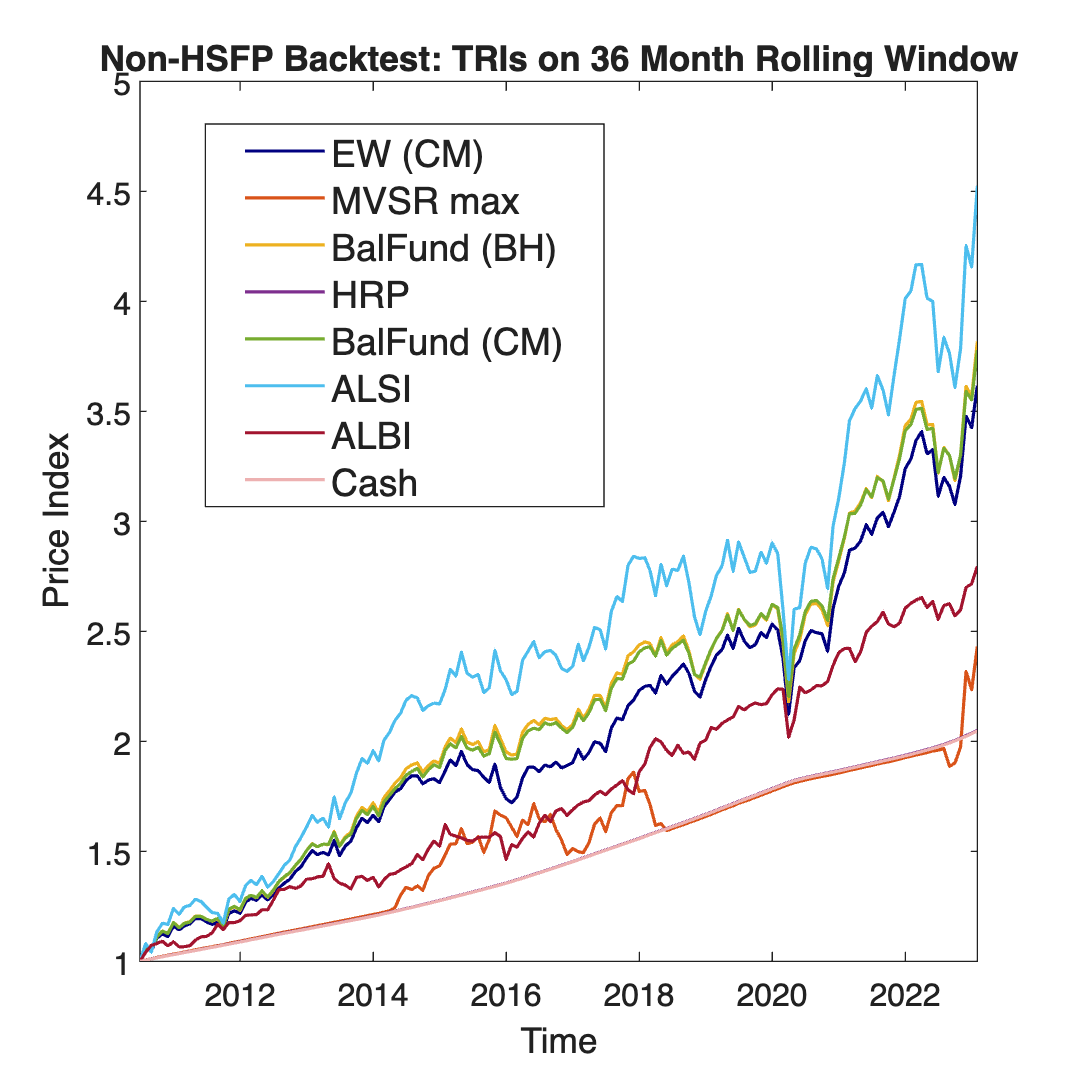

Z = [Opt_tsWts{2,2}];
Y = Rolling_portfolioSet.Time;
ribbon(Y,Z,0.5)


title(['Optimal Weight Surfaces for ' Opt_tsWts{1,2} ' Portfolio'],'FontSize', 13 )
colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue
colormap(colours)
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALB Index','FINI15 Index','INDI25 Index','RESI20 Index','Cash'});
ylabel('Time')
zlabel('Opt Weight')

view([57.336 78.226])

Y = Rolling_portfolioSet.Time;
Z = [Opt_tsWts{2,2}];
h = ribbon(Y,Z,0.5);
title('Optimal Weight Surfaces for MV-SR Portfolio','FontSize', 16 )
colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue
colormap(colours)
h(1).EdgeColor = "white";
h(2).EdgeColor = "white";
h(3).EdgeColor = "white";
h(4).EdgeColor = "white";
h(5).EdgeColor = "white";
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALB Index','FINI15 Index','INDI25 Index','RESI20 Index','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([57.336 78.226])

**Export Optimal Weight Surface Plot**

exportName = 'wts_surface_NoneHSFP_MV.pdf';
exportgraphics(h,fullfile(imageExportpath,exportName),'Resolution',300);

### 3.2 Visualising Control Surfaces 

f = figure;
% Set Y axis for datetime object
Y = Rolling_portfolioSet.Time;
% Create fig
% f1 = figure('OuterPosition', [100, 100, 600, 600]);
sgtitle(['Non-HSFP Backtest: ', num2str(Window), ' Month Rolling Window'], 'FontSize', 13);
% plot grid
numRows = 2;
numCols = 3;

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue


% Colour palette: Hexadecimal Colour Codes
BF_colours = [0.4660 0.6740 0.1880; % green
     0.3010 0.7450 0.9330; % light blue
   0 0.4470 0.7410]; % dark blue

%%% 1. Performance Plot %%%%
subplot(numRows, numCols, 1);
axis square;
perform_colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = perform_colours(mod(i-1, size(perform_colours, 1))+1, :);
    plot(Rolling_portfolioSet.Time, Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 9);
xlabel('Time', 'FontSize', 15);
% ylim([0.9, 4.5])
title('Non-HSFP: Portfolio Cummulative TRIs', 'FontSize', 9);
legend(Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 6);
set(gca, 'FontSize', 9);

%%% 2. Equally Weighted %%%%
ax(1) = subplot(numRows, numCols, 2);
grid on
Z = [Opt_tsWts{2,1}];
h = ribbon(Y,Z,0.5);
colormap(ax(1),colours);
for i = 1:numel(h)
    h(i).EdgeColor = colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALBI','FINI15','INDI25','RESI20','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([56.7207012835473 33.9084446444713]);
title(['Non-HSFP: ' Opt_tsWts{1,1} ' Portfolio Controls'],'FontSize', 9);


%%% 3.  MV SR Max %%%%
ax(2) = subplot(numRows, numCols, 3);
Z = [Opt_tsWts{2,2}];
grid on
h1 = ribbon(Y,Z,0.5);
colormap(ax(2),colours);
for i = 1:numel(h1)
    h1(i).EdgeColor = colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALBI','FINI15','INDI25','RESI20','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([57.336 78.226])
title(['Non-HSFP: ' Opt_tsWts{1,2} ' Portfolio Controls'],'FontSize', 9);


%%% 4. BF B-H %%%%
ax(3) = subplot(numRows, numCols, 4);
Z = [Opt_tsWts{2,3}];
h2 = ribbon(Y,Z,0.5);
colormap(ax(3),BF_colours);
for i = 1:numel(h2)
    h2(i).EdgeColor = BF_colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:3,'xticklabel',{'ALSI', 'Cash','ALBI'});
ylabel('Time')
zlabel('Opt Weight')
view([60.3745064177363 23.430953351469])
title(['Non-HSFP: ' Opt_tsWts{1,3} ' Portfolio Controls'],'FontSize', 9);

%%% 5. HRP %%%%
ax(4) = subplot(numRows, numCols, 5);
Z = [Opt_tsWts{2,4}];
h3 = ribbon(Y,Z,0.5);
colormap(ax(4),colours);
for i = 1:numel(h3)
    h3(i).EdgeColor = colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALBI','FINI15','INDI25','RESI20','Cash'});
ylabel('Time')
zlabel('Opt Weight')
view([61.2860583430572 42.5455046439628])
title(['Non-HSFP: ' Opt_tsWts{1,4} ' Portfolio Controls'],'FontSize', 9);

%%% 6. BF CM %%%%
ax(5) = subplot(numRows, numCols, 6);
Z = [Opt_tsWts{2,5}];
h4 = ribbon(Y,Z,0.5);
colormap(ax(5),BF_colours);
for i = 1:numel(h4)
    h4(i).EdgeColor = BF_colours(i,:);
end
xlabel('Asset Class')
set(gca,'xtick',1:3,'xticklabel',{'ALSI', 'Cash','ALBI'});
ylabel('Time')
zlabel('Opt Weight')
view([53.0820910151692 23.4309538458165])
title(['Non-HSFP: ' Opt_tsWts{1,5} ' Portfolio Controls'],'FontSize', 9);



UnAdj_36RollW_Output_Plot = f;
hold off;


subplot(2,3,2)
view([58.18 17.39])
subplot(2,3,3)
view([69.23 58.45])
subplot(2,3,5)
view([60.95 25.20])

% Export the fig as a PDF
UnAdj_RollW_Wt_Surfaces_Plot = f;
hold off


**Export Unconstrained Traditional Optimal Weight Surface Plot**

exportName = 'UnAdj_RollW_Wt_Surfaces_Plot.pdf';
exportgraphics(UnAdj_RollW_Wt_Surfaces_Plot,fullfile(imageExportpath_,exportName),'Resolution',300, 'ContentType', 'image');

# Section 2: Retry using WINSORISED Returns Data

% addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes//datahelpers/functions/'));

Return_matrix = table2array(M_Ret_TT);

## 1. Apply Winsorisation

W_sd = 2;
[wx,b,ui,li] = winsorise(Return_matrix,W_sd);
winsorisedRet_TT = array2timetable(wx,'RowTimes',M_Ret_TT.Time);
winsorisedRet_TT.Properties.VariableNames = M_Ret_TT.Properties.VariableNames;

### 1.1 Visualise PRE-winsorised data vs Post winsorided data:

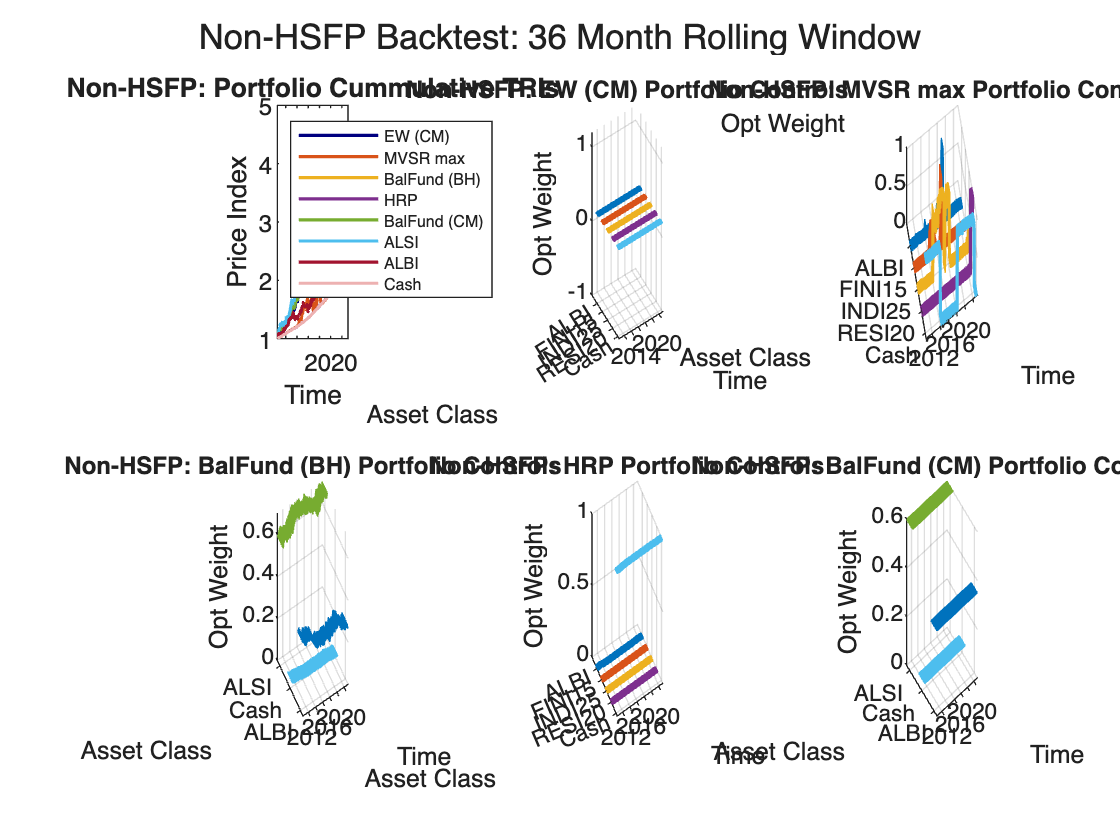

figure('InnerPosition', [100, 100, 600, 600]);
histogram(Return_matrix, 'FaceColor', [0.8, 0.8, 0.8])

title('Distrubution of Non-Winsorised Monthly Returns', 'FontSize',13)
xlabel('Returns', 'FontSize',13);
ylabel('Frequency', 'FontSize',13);
NonWinsorided_Dist_Returns_Hist = gcf;

### 1.2 Visualise POST-winsorised data vs Post winsorided data:

grey_green_col = 1/255*[0,104,87];
figure('InnerPosition', [100, 100, 600, 600]);
histogram(wx, 'FaceColor', grey_green_col);
title('Distrubution of WINSORISED (2sd.) Monthly Returns', 'FontSize',13)
xlabel('Returns', 'FontSize',13);
ylabel('Frequency', 'FontSize',13);
Winsorided_Dist_Returns_Hist = gcf;

**Export PRE-Winsorised Returns Histogram **

exportName = 'NonWinsorided_Dist_Returns_Hist.pdf';
exportgraphics(NonWinsorided_Dist_Returns_Hist,fullfile(imageExportpath_st,exportName),'Resolution',300);

**Export WINSORISED Returns Histogram **

exportName = 'Winsorided_Dist_Returns_Hist.pdf';
exportgraphics(Winsorided_Dist_Returns_Hist,fullfile(imageExportpath_st,exportName),'Resolution',300);

### 1.3 Set up backtest object again with winsorised data

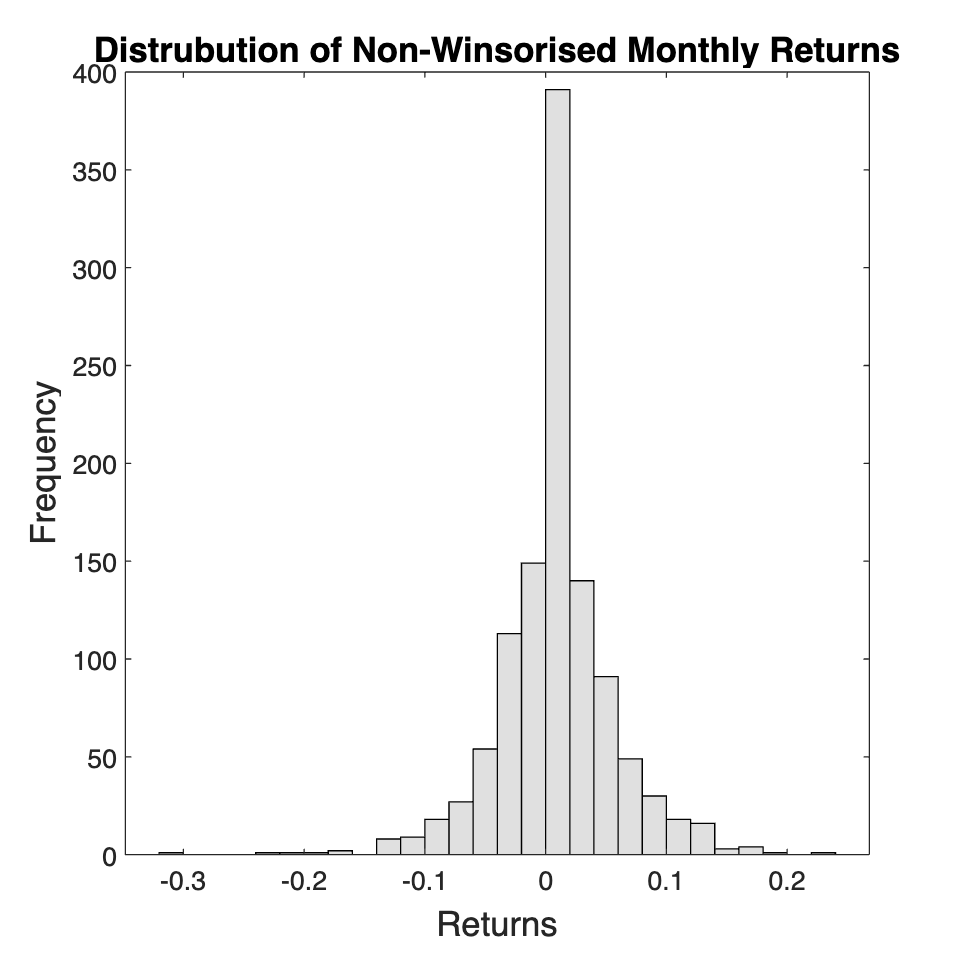

W_backtest_object = struct('returns',[],'Wts_lb',[],'Wts_ub',[],'signals',[],'method',[], 'parameters',[]);
%%%% USE WINSORISED DATA AS INPUT %%%%%%
W_backtest_object.returns = winsorisedRet_TT;
% Ensemble needs more than 1 signal series
W_backtest_object.Signals = timetable(SIG_SMOOTHED_TT.Time, ...

    SIG_SMOOTHED_TT.lagged_SAMYM3Y_Index, SIG_SMOOTHED_TT.SAVIT40_Index);
% NB: needs to be a timetable object
W_backtest_object.method = 'none';
W_backtest_object.parameters = hsfp_parameters; 

### 1.4 Call the backtest_function

Window = 36;
[SR_dif_t,geo_SR_dif,W_Rolling_portfolioSet,W_Realised_tsPIndx,W_Realised_tsPRet,W_Opt_tsWts, W_cov_con_n] = backtest_analysis(W_backtest_object, Window,0);

### 1.5 Visualise Winsor Backtest 

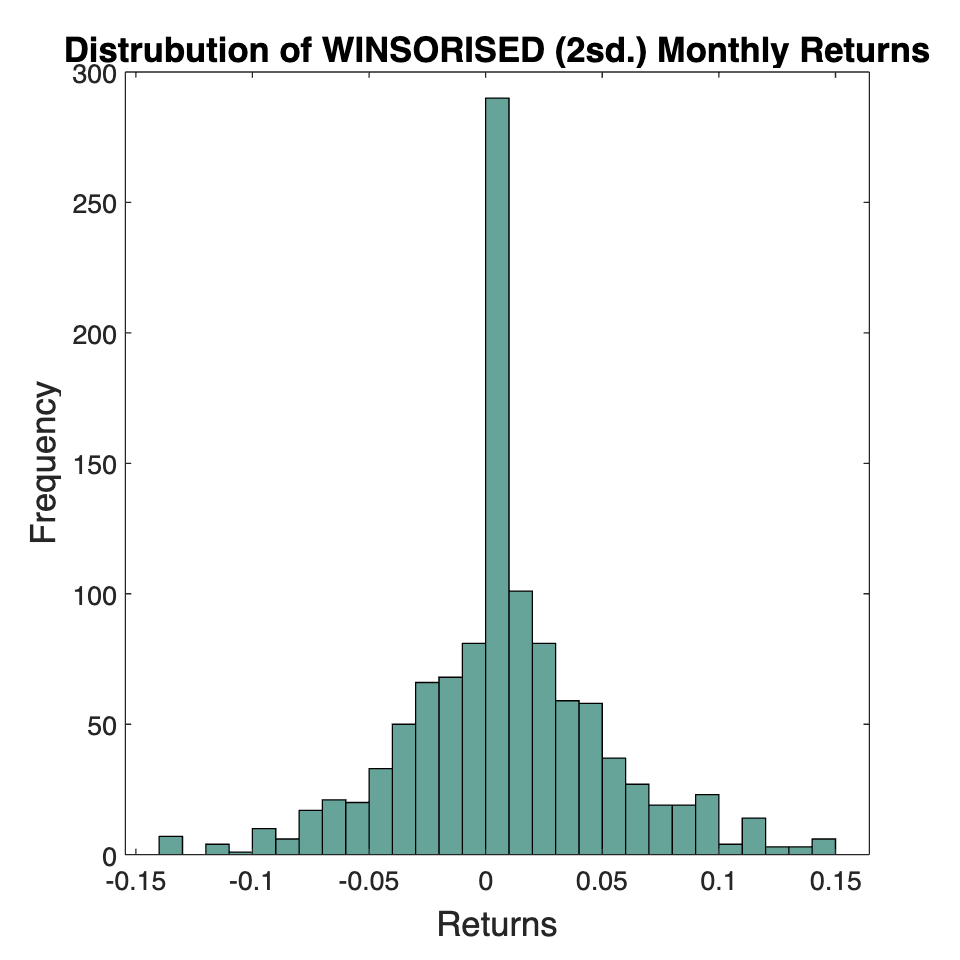

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];    % blue

    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(W_Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(W_Rolling_portfolioSet.Time, W_Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
title([num2str(W_sd) 'sd. WINSORISED Non-HSFP Backtest: TRIs on ', num2str(Window), ' Mth Rolling Window'], 'FontSize', 16);
legend(W_Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
Winsorised3_UnAdj_36RollW_Output_Plot = gcf;
hold off;

legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])


**Export Unconstrained Traditional Optimal Weight Surface Plot**

exportName = 'Winsorised3_UnAdj_36RollW_Output_Plot.pdf';
exportgraphics(Winsorised3_UnAdj_36RollW_Output_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

# Section 3: Retry using REGULARISE COVARIANCE of Returns Data

## Preamble 

Check condition number of the covariance matrix:

A matrix with a high condition number indicates that it s is close to being singular and thus 

Write a loop that calculates the condition number of each calculated convarinace at each iteration if the backtest and plot it. 

full_cov = cov(table2array(M_Ret_TT));

condition_n = cond(full_cov,inf)

## 1. Visualise Condition Numbers of Covariance Matrices through backtest (BEFORE REGULARISING)

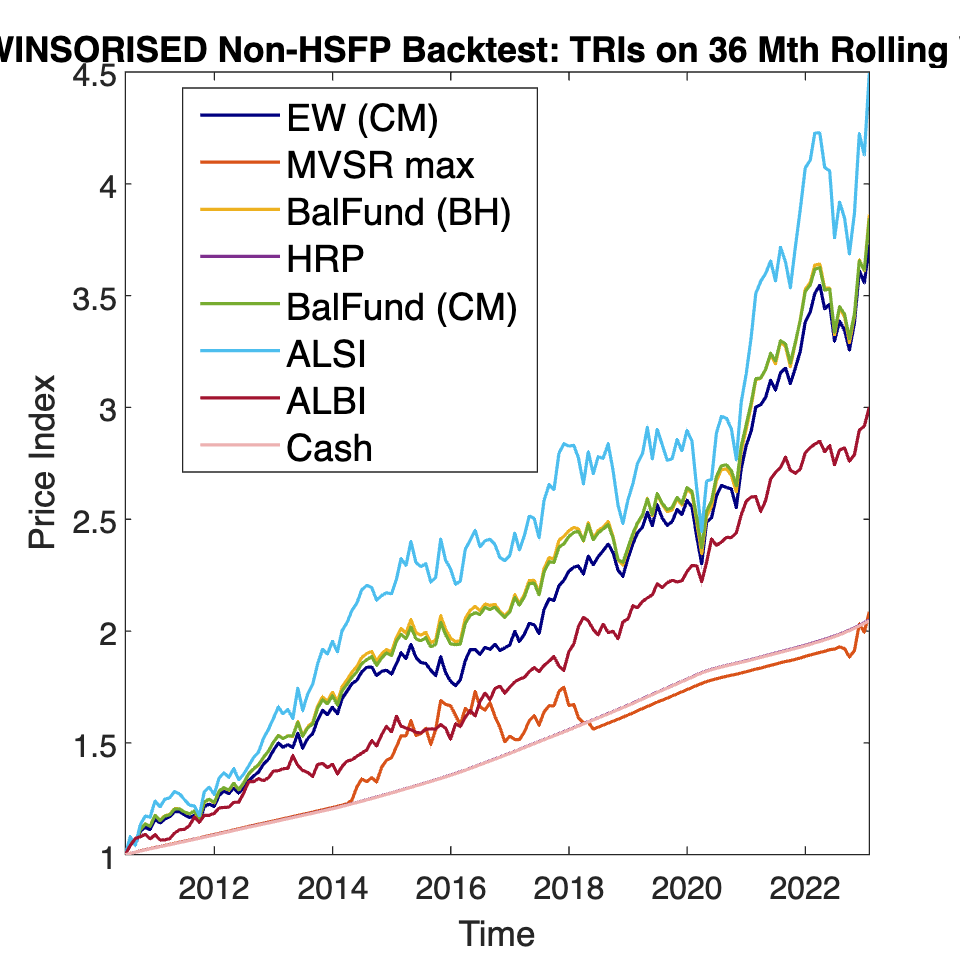

plot(Rolling_portfolioSet.Time,cov_con_n, 'Color', [128 128 128]/255, 'LineWidth',2)
ax = gca;
ax.YAxis.Exponent = 0;
title('Pre-Regularisation: Covariance Condition Numbers', 'FontSize',13)
ylabel('Condition Number', 'FontSize',13);
xlabel('Time','FontSize',13)

ax2 = gca;
chart = ax2.Children(1);
datatip(chart,datetime(2020,4,30,0,0,0),4.34e+05);
PreReg_Cov_Con_Curve = gcf;

**Export PRE-REgularised COV Condition Number Curve **

exportName = 'PreReg_Cov_Con_Curve.pdf';
exportgraphics(PreReg_Cov_Con_Curve,fullfile(imageExportpath_st,exportName),'Resolution',300);

## 2. Regularise Covaraince Matrices

TEST of Regularisation term

% Regularization parameter (lambda)
% reg_lambda = 0.5;
% 
% % Identity matrix of the same size as Cov
% n = size(full_cov, 1);  % Assuming S is a square matrix
% I = eye(n);
% 
% % Compute the regularized covariance matrix (R)
% R = full_cov + reg_lambda * I;

### 2.1 Call the backtest_function

Window = 36;
reg_lambda = 0.005;
[SR_dif_t,geo_SR_dif,Reg_Rolling_portfolioSet,Reg_Realised_tsPIndx,Reg_Realised_tsPRet,Reg_Opt_tsWts,Reg_cov_con_n] = backtest_analysis(backtest_object, Window,0,reg_lambda);

condition_n = 5.1255e+03

### 2.2 Visualise Condition Numbers of Covariance Matrices through backtest (POST REGULARISING)

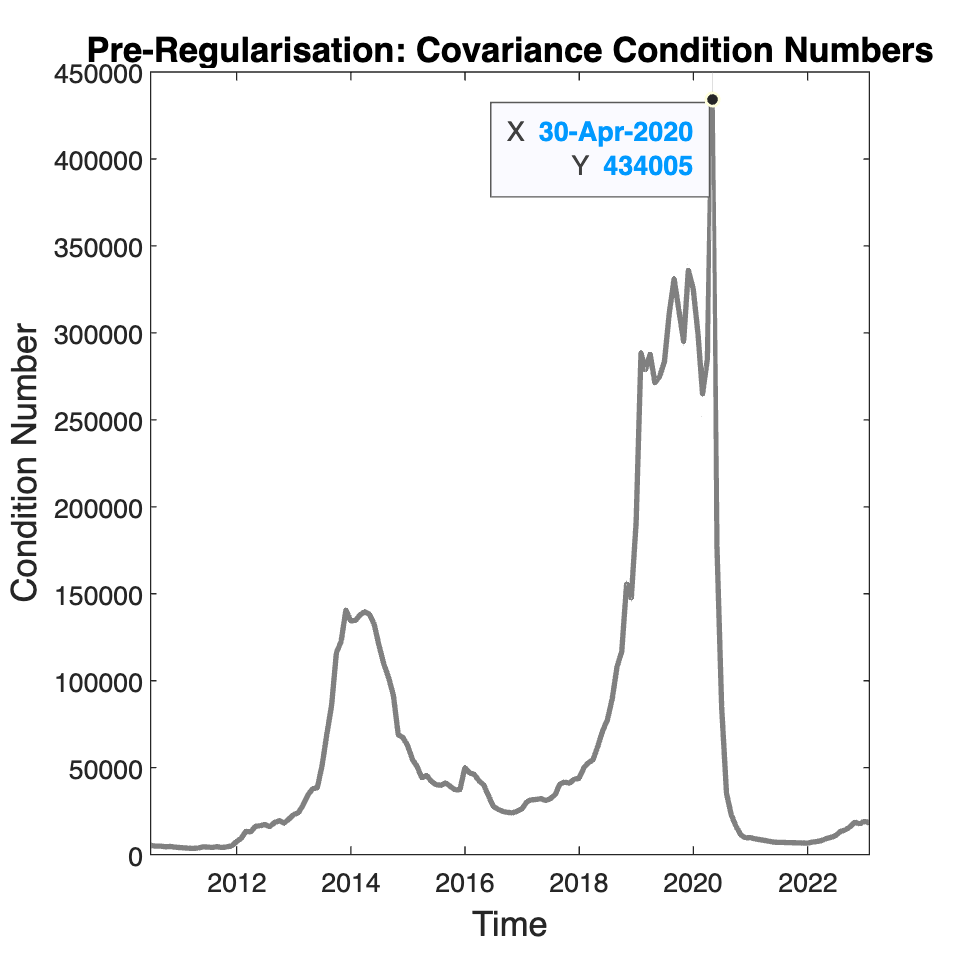

plot(Rolling_portfolioSet.Time,Reg_cov_con_n, 'Color',grey_green_col, 'LineWidth',2)
ax = gca;
ax.YAxis.Exponent = 0;
title('Post-Regularisation (\lambda = 0.005): Covariance Condition Numbers ', 'FontSize',13)
ylabel('Condition Number', 'FontSize',13);
xlabel('Time', 'FontSize',13)

ax3 = gca;
chart2 = ax3.Children(1);
datatip(chart2,datetime(2020,2,29,0,0,0),1.837);

datatip(chart2,datetime(2020,5,31,0,0,0),2.808);
PostReg_Cov_Con_Curve = gcf;

ax2 = gca;

**Export POST-REgularised COV Condition Number Curve **

exportName = 'PostReg_Cov_Con_Curve.pdf';
exportgraphics(PostReg_Cov_Con_Curve,fullfile(imageExportpath_st,exportName),'Resolution',300);

### 2.3 Visualise regularised Backtest 

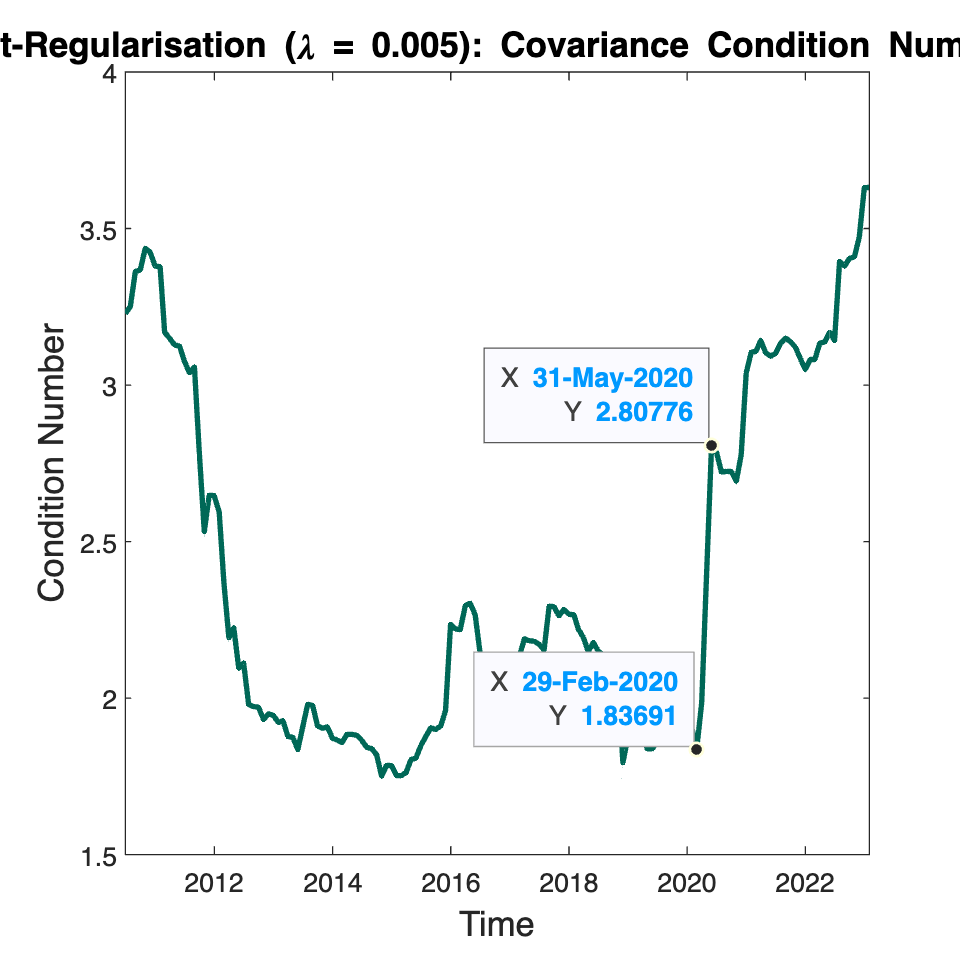

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(Reg_Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(Reg_Rolling_portfolioSet.Time, Reg_Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
ylim([1 4.6])
title(['REGULARISED (\lambda = ' num2str(reg_lambda) ') Non-HSFP Backtest: TRIs on ', num2str(Window), ' Mth Rolling Window'], 'FontSize', 16);
legend(Reg_Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
Reg0_005_UnAdj_36RollW_Output_Plot = gcf;
hold off;


legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])

**Export REGULARISED backtest plot**

exportName = 'Reg0_005_UnAdj_36RollW_Output_Plot.pdf';
exportgraphics(Reg0_005_UnAdj_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

# Section 4: 5% Cash Constraint

## 1. Call the backtest_function

Window = 36;
backtest_object.Wts_lb = [ 0 0 0 0 0.05]; 
backtest_object.Wts_ub = [ 1 1 1 1 0.05];
HRP_cash = 1;
[SR_dif_t,geo_SR_dif,CCReg_Rolling_portfolioSet,CCReg_Realised_tsPIndx,CCReg_Realised_tsPRet,CCReg_Opt_tsWts,CCReg_cov_con_n] = backtest_analysis(backtest_object, Window,HRP_cash);

### 1.1 Visualise Cash Constrainted backtest

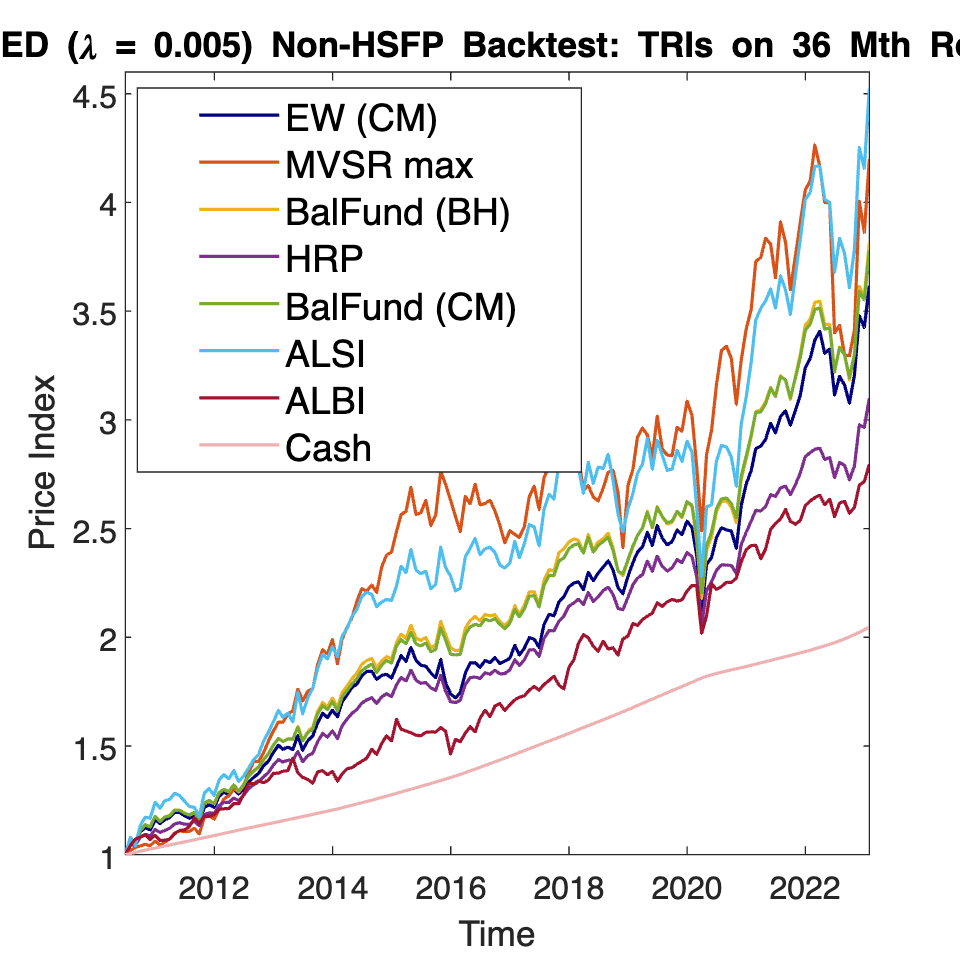

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(CCReg_Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(CCReg_Rolling_portfolioSet.Time, CCReg_Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);

xlabel('Time', 'FontSize', 15);
ylim([1 4.6])
title(['5% Cash Constraint Non-HSFP Backtest: TRIs on ', num2str(Window), ' Mth Rolling Window'], 'FontSize', 16);
legend(CCReg_Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
CC_UnAdj_36RollW_Output_Plot = gcf;
hold off;



legend("Position", [0.1896,0.58723,0.36979,0.2424])

# Section 5: Retry using Winsorised RETURNS & REGULARISE COVARIANCE of Returns Data

## 1. Call the backtest_function

Window = 36;
reg_lambda = 0.005;
[SR_dif_t,geo_SR_dif,WReg_Rolling_portfolioSet,WReg_Realised_tsPIndx,WReg_Realised_tsPRet,WReg_Opt_tsWts,WReg_cov_con_n] = backtest_analysis(W_backtest_object, Window,0,reg_lambda);

### 1.1 Visualise Winsor & Reg Backtest 

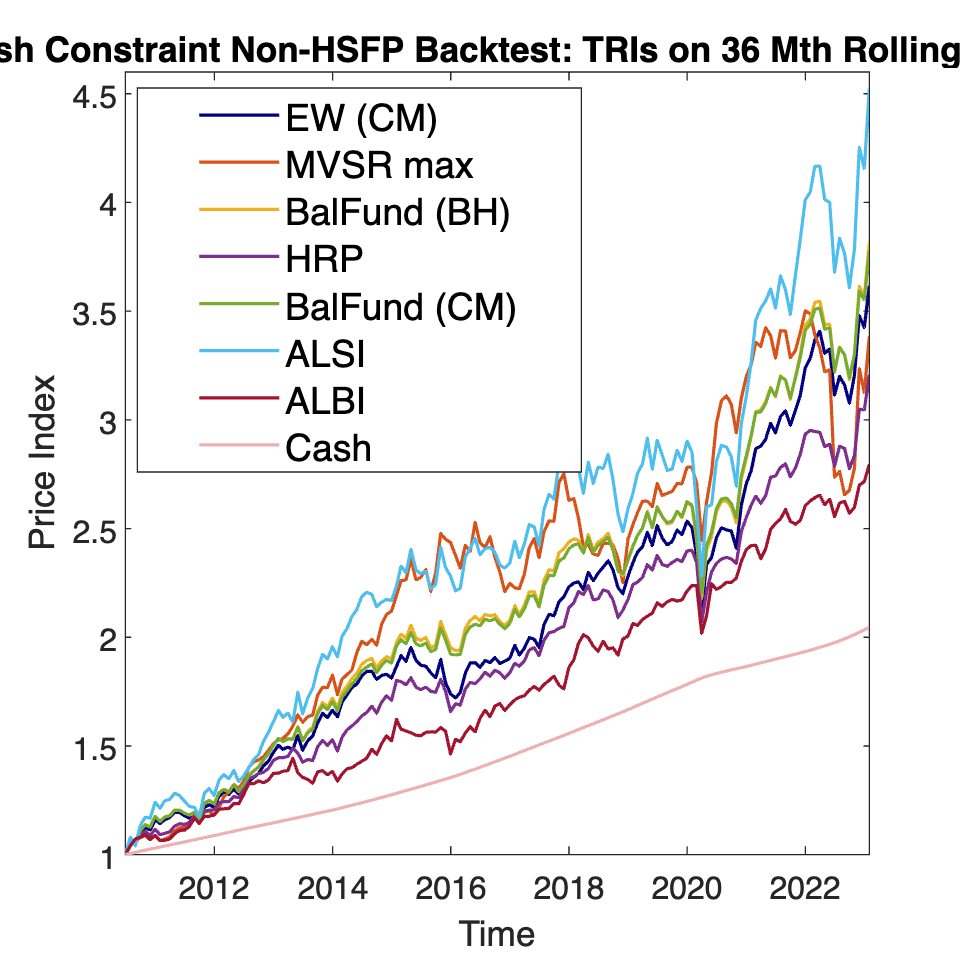

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(WReg_Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(WReg_Rolling_portfolioSet.Time, WReg_Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
ylim([1 4.6])
title(['WINSORISED & REGULARISED Non-HSFP Backtest: TRIs on ', num2str(Window), ' Mth Rolling Window'], 'FontSize', 16);
legend(WReg_Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
Winsor2_Reg0_005_UnAdj_36RollW_Output_Plot = gcf;
hold off;

legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])

**Export Winsorised & REGULARISED backtest plot**

exportName = 'Winsor2_Reg0_005_UnAdj_36RollW_Output_Plot.pdf';
exportgraphics(Winsor2_Reg0_005_UnAdj_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

# Section 6: Retry using Winsorised & Regularised as well as 5% cash constraint

## 1. Set up backtest object again with winsorised data and cash constraint

% Options:   - none (default) 

%            - rolling_w

%            - exp_decay

%            - crisp

%            - kernel

%            - e_pooling

%            - ew_ensemble

%            - cb_ensemble

Window_len = 12;
tau = 12;
alpha = 0.1;
z_target = 'latest';
gamma = 2;
h = 0.5;
ensemble_wt_method = 'log-linear';
%%%%% ********** Problem lies with EPool_prior when going into BT as it
%%%%%%  depends on size of sig_data... need to integrate into BT or into the ep_probs.m function itself....
%%% Therefore, cannot currently test ep, ew_ensemble or cb_ensemble until
%%% ep is resolved.
tau_prior = 1*12; % Ann did 5 yrs


% Rfr = mean(M_Ret_TT.Cash);
hsfp_parameters = struct('window',[],'tau',[],'alpha',[],'z_target',[], ...
    'gamma',[],'h',[], 'tau_prior',[],'ensemble_wt_method',[]);
hsfp_parameters.window = Window_len;
hsfp_parameters.tau = tau;
hsfp_parameters.alpha = alpha;
hsfp_parameters.z_target = z_target;
hsfp_parameters.gamma = gamma;
hsfp_parameters.h = h;
hsfp_parameters.tau_prior = tau_prior;
hsfp_parameters.ensemble_wt_method = ensemble_wt_method;

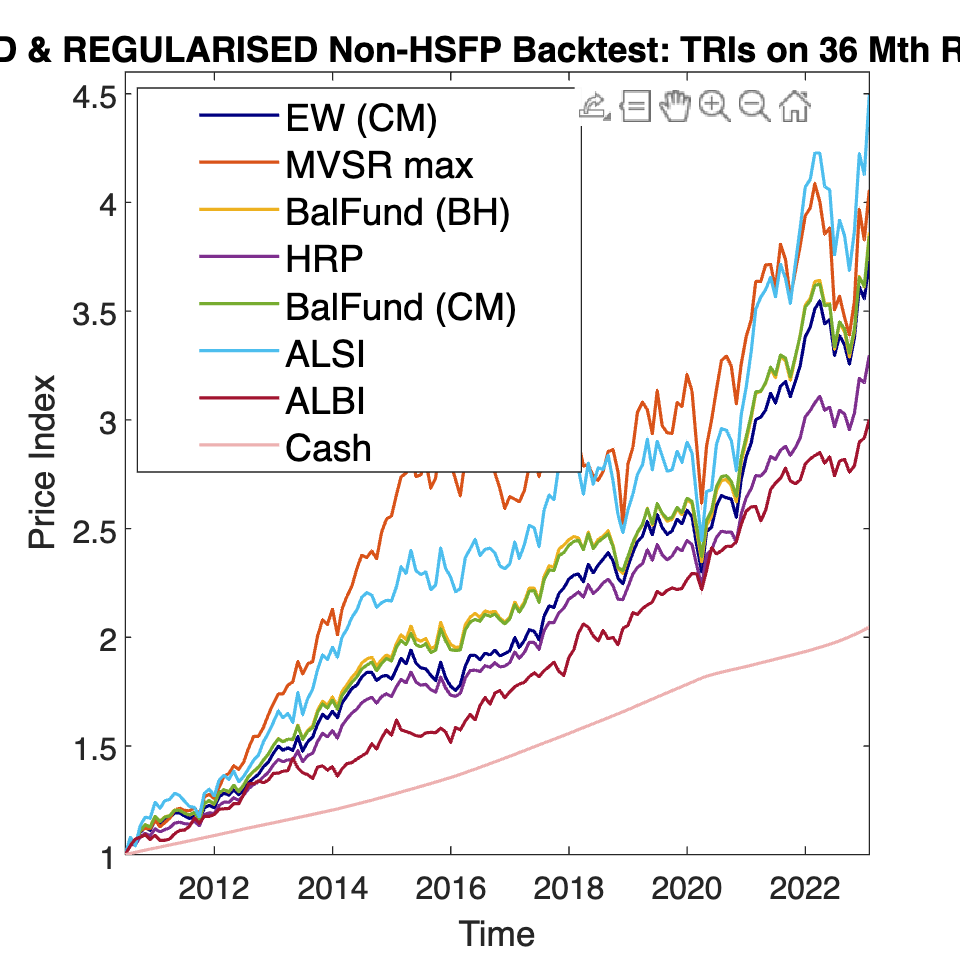

reg_lambda = 0.005;
CConstraint_backtest_object = struct('returns',[],'Wts_lb',[],'Wts_ub',[],'signals',[],'method',[], 'parameters',[]);
%%%% USE WINSORISED DATA AS INPUT %%%%%%
CConstraint_backtest_object.returns = M_Ret_TT;
% Control bounds: lower and upper bounds for asset weights 
% CConstraint_backtest_object.Wts_lb = [ 0 0 0 0 0 ]; 
% CConstraint_backtest_object.Wts_ub = [ 1 1 1 1 0.05];
% Ensemble needs more than 1 signal series

CConstraint_backtest_object.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
% NB: needs to be a timetable object
CConstraint_backtest_object.method = 'crisp';
CConstraint_backtest_object.parameters = hsfp_parameters; 

### 1.1 Call the backtest_function

Window = 36;
[CConstraint_Rolling_portfolioSet,CConstraint_Realised_tsPIndx,CConstraint_Realised_tsPRet,CConstraint_Opt_tsWts, CConstraint_cov_con_n] = backtest_analysis(CConstraint_backtest_object, Window);

## 2. Visualise Cash Constrained Winsor & Reg Backtest 

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(CConstraint_Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(CConstraint_Rolling_portfolioSet.Time, CConstraint_Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
ylim([1 4.6])
title(['WINSORISED & REGULARISED Non-HSFP Backtest: TRIs on ', num2str(Window), ' Mth Rolling Window'], 'FontSize', 16);
legend(CConstraint_Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
Cash_Const_Reg0_005_UnAdj_36RollW_Output_Plot = gcf;
hold off;

legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])

Z = [CConstraint_Opt_tsWts{2,2}];
Y = Rolling_portfolioSet.Time;
ribbon(Y,Z,0.5)

title(['Optimal Weight Surfaces for ' CConstraint_Opt_tsWts{1,2} ' Portfolio'],'FontSize', 13 )
colours = [0 0.4470 0.7410; % dark blue
    0.8500 0.3250 0.0980; % orange
    0.9290 0.6940 0.1250; % yellow
    0.4940 0.1840 0.5560; % purple
    0.3010 0.7450 0.9330]; % light blue
colormap(colours)
xlabel('Asset Class')
set(gca,'xtick',1:5,'xticklabel',{'ALB Index','FINI15 Index','INDI25 Index','RESI20 Index','Cash'});
ylabel('Time')
zlabel('Opt Weight')

view([57.336 78.226])

# Section 7. Testing Invariants in the HS-FP model using 5% and Winsorised Returns

## The code below functions as it was introduced after OOPbacktest_analysis was built. Here it is used to test out the use of invariants for the HS-FP model. 

M_Ret_TT = M_Ret_TT(2:end,:);

CC = 0.05; 
W_sd = 2;
HSFPparameters_test = HSFPparameters;
test_class1 = backtestedPortfolios;
test_class1.HSFPparameters = HSFPparameters_test;
test_class1.Returns = M_Ret_TT(2:end,:);
test_class1.Invariants = M_Invariant_TT;
test_class1.Method =  'crisp';
test_class1.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SAMYM3Y_Index);
test_class1.WinsorStd = W_sd;
test_class1.CashConstraint = CC;
% No regulariasation applied (based on prior dsr data processing analysis)
test_class1.RegLambda = 0.00;

%%% Run backtest
% profile on
test1_bcktest = OOPbacktest_analysis(test_class1);
% profile off
%%% Plot performance Curves 
PerformancePlot(test1_bcktest);